### Computational Method in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Initial Value Problems

#### Learning outcomes

On successful completion of this page readers will be able to:

- Identify an initial value problem;

- Derive the Euler method and apply it to solve first-order ordinary differential equations;

- Express a higher-order ODE as a system of first-order ODEs;

- Apply an ODE solver to solve a system of ODEs.

An [Initial Value Problem](https://en.wikipedia.org/wiki/Initial_value_problem) (IVP) is written as an [Ordinary Differential Equation](https://en.wikipedia.org/wiki/Ordinary_dif) (ODE) where the initial solution at the lower boundary of the domain is known. For example,


$$y\prime = f(t, y), \qquad t \in [t_{\min}, t_{\max}],  \qquad y(t_{\min}) &= y_0.$$


Here a first-order ODE $y\prime=f(t,y)$ is defined over the domain $t\in [t_{\min}, t_{\max}]$ and the initial solution $y(t_{\min})$ is the known value $y_0$. 

In most real world practical applications, IVPs cannot be solved using analytical methods so instead we use computational methods called **ODE solvers** to approximate the solutions. The simplest ODE solver is the Euler method.

### The Euler method

The [Euler method](https://en.wikipedia.org/wiki/Euler_method) for solving the first-order Ordinary Differential Equation (ODE) can be derived very easily by truncating the [Taylor series](https://en.wikipedia.org/wiki/Taylor_series) after the first-order term


$$y_{n+1} = y_n + hf(t_n, y_n),$$


where the subscript notation used is $y_{n+1} = y(t + h)$, $y_n = y(t_n)$.

To apply the Euler method to solve an IVP we loop through the domain and calculate the values of $y_{n+1}$ using the Euler method with the known values $t_{n}$ and $y_n$.

#### Example 1

Calculate the first two steps of the Euler method when used to solve the following IVP


$$y\prime =\sin^2(t)y, \qquad t\in [0,5], \qquad y(0)=1.$$


using a step length $h=0.5$.

Since we have $t_0=0$ and $y_0=1$ then


$$y_1 = y_0 + h\sin^2(t_0)y_0 = 1 + 0.5 \sin^2(0)(1) = 1, \qquad \qquad \quad t_1 = t_0 + h = 0 + 0.5 = 0.5,  \\
y_2 = y_1 + h\sin^2(t_1)y_1 = 1 + 0.5\sin^2(0.5)(1) = 1.1149, \qquad t_2 = t_1 + h = 0.5 + 0.5 = 1.0.$$


#### Example 2

Calculate the solution of the IVP from example 1 over the whole domain $t\in[0, 5]$ using the Euler method with a step length of $h=0.5$ and compare it to the exact solution given by


$$y=e^{(t - \sin(t)\cos(t))/2}$$


The function called euler below is defined in the Functions section at the bottom of this page calculates the solution to an IVP using the Euler method. The input arguments are `f` is the name of the function the defines the ODE, `tspan` is a two-element array containing the lower and upper bounds of the $t$ domain, `y0` is the initial value of $y$ at the lower bound and `h` is the step length.

The program below invokes the Euler method to solve this IVP.

% Define ODE function
f = @(t, y) sin(t).^2 * y;

% Define exact solution
exact = @(t) exp(0.5 * (t - sin(t) .* cos(t)));

% Define IVP parameters
tspan = [ 0, 5 ];
y0 = 1;
h = 0.5;

% Invoke Euler method to solve IVP
[t, y] = euler(f, tspan, y0, h);

% Output solution table
table = sprintf(' t    Euler   Exact \n--------------------\n');
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', t(n), y(n), exact(t(n)))];
end
fprintf(table)

 t    Euler   Exact 
--------------------
0.00  1.0000  1.0000
0.50  1.0000  1.0404
1.00  1.1149  1.3135
1.50  1.5096  2.0436
2.00  2.2607  3.2845
2.50  3.1953  4.4359
3.00  3.7675  4.8059
3.50  3.8050  4.8830
4.00  4.0391  5.7699
4.50  5.1958  8.5589
5.00  7.6783 13.9573


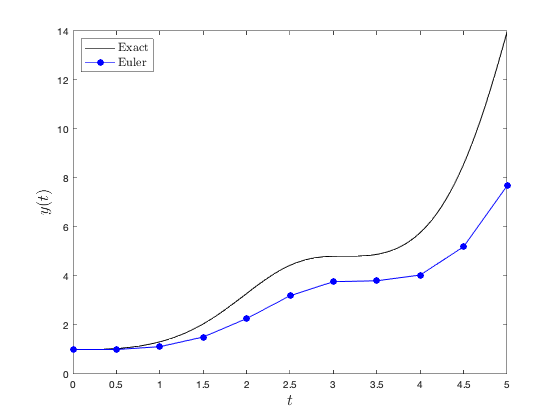

% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact(t1), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'blue')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'Euler');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that the solution using the Euler method deviates from the exact solution. This is because the Euler method is a first-order method and the truncation errors at each step accumulate as we step through the solution. One way to improve our solution is to use a smaller step length.

#### Example 3

Repeat the solution of the IVP in example 2 using a step length of $h=0.1$ and compare the solution with the exact solution and the one obtained using $h=0.5$.

% Invoke Euler method to solve IVP
[t1, y1] = euler(f, tspan, y0, 0.5);
[t2, y2] = euler(f, tspan, y0, 0.1);

% Output solution table
table = ' t    h=0.5   h=0.1   Exact \n----------------------------\n';
for n = 1 : length(t1)
    table = [table , sprintf('%3.2f %7.4f %7.4f %7.4f\n', ...
        t1(n), y1(n), y2(1 + 5*(n-1)), exact(t1(n)))];
end
fprintf(table)

 t    h=0.5   h=0.1   Exact 
----------------------------
0.00  1.0000  1.0000  1.0000
0.50  1.0000  1.0291  1.0404
1.00  1.1149  1.2626  1.3135
1.50  1.5096  1.9018  2.0436
2.00  2.2607  3.0133  3.2845
2.50  3.1953  4.1223  4.4359
3.00  3.7675  4.5394  4.8059
3.50  3.8050  4.5919  4.8830
4.00  4.0391  5.2940  5.7699
4.50  5.1958  7.5957  8.5589
5.00  7.6783 12.1225 13.9573


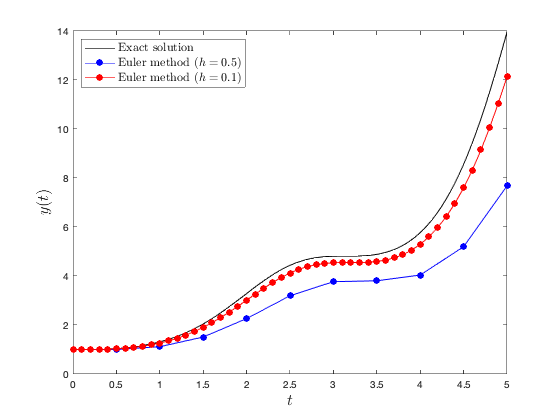

% Plot solutions
t3 = linspace(tspan(1), tspan(2), 100);
plot(t3, exact(t3), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'b')
plot(t2, y2, 'ro-', 'markerfacecolor', 'r')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact solution', 'Euler method ($h=0.5$)', 'Euler method ($h=0.1$)');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that although using a smaller step length has increased the accuracy of the solution it still doesnt match the exact solution. The Euler method is easy to derive and apply but is not very accurate.

## Solving higher-order ordinary differential equations

The numerical methods that are applied to calculate the solutions to ODEs can only be applied to first-order ODEs. To apply them to higher-order ODEs we first need to rewrite them as a system of first-order ODEs.

Consider the $N$th-order ODE

$y^{(N)} = f(t, y, y\prime, y\prime\prime, \ldots, y^{(N-1)})$.

If we let $y_1=y$, $y_2=y\prime$, $y_3=y\prime\prime$ and so on up to $y_N=y^{(N-1)}$ then we have


$$y_1\prime = y_2,\\
y_2\prime = y_3, \\
\vdots \\
y_N\prime = f(t, y_1, y_2, y_3, \ldots, y_N).$$
 

This is a system of $N$ first-order ODEs. We can apply our numerical methods for solving ODEs to each equation in the system to give an equivalent solution to the $n$th-order ODE.

#### Example 4

Rewrite the following third-order ODE as a system of three first-order ODEs

$y\prime\prime\prime + yy\prime\prime - 2y\prime + ty\prime\prime - 10 = 0$.

Let $y_1=y$, $y_2=y\prime$, $y_3=y\prime\prime$ then we can rewrite this ODE using


$$y_1\prime=y_2, \\
y_2\prime = y_3, \\
y_3\prime = -y_1y_3 + 2y_2 + ty_3$$


### Solving systems of ordinary differential equations

Consider a system of $N$ first-order ODEs written in the form


$$y_1\prime = f_1(t, y_1), \\
y_2\prime = f_2(t, y_2), \\
\vdots \\
y_N\prime = f_N(t, y_N).$$


Let $\mathbf{y} = \pmatrix{y_1 \cr y_2 \cr \vdots \cr y_N }$ and $F(t, \mathbf{y}) = \pmatrix{ f_1(t, y_1) \cr f_2(t, y_2) \cr \vdots \cr f_N(t,y_N)}$ then we can write the system in vector form

$\mathbf{y}\prime = F(t, \mathbf{y})$.

#### Example 5

Calculate two steps of the Euler method used to solve the following IVP

$y\prime\prime + y = 0, \qquad t \in [0, 10], \qquad y(0) = 2, \qquad y'(0) = 0$,

using a step length of $h=0.1$.

First we need to rewrite the second-order ODE as two first-order ODEs. Let $y_1=y$ and $y_2=y\prime$ then


$$y_1\prime=y_2, \qquad \quad y_1(0)=2, \\ y_2\prime = -y_1, \qquad \, \,y_2(0)=0,$$


and we have

$\mathbf{y} = \pmatrix{ y_1 \cr y_2 }, \qquad F(t, \mathbf{y}) = \pmatrix{ y_2 \cr -y_1}$.

Calculating the first two steps of the Euler method:


$$\mathbf{y}_1 = \mathbf{y}_0 + hF(t_n,\mathbf{y}_0) = \pmatrix{2\cr0}+0.1\pmatrix{0\cr-2}=\pmatrix{2\cr-0.2}, \\
\mathbf{y}_2 = \mathbf{y}_1 + hF(t_n,\mathbf{y}_1) = \pmatrix{2\cr -0.2} + 0.1\pmatrix{-0.2 \cr -2} = \pmatrix{1.98 \cr -0.4}.$$


#### Example 6

Calculate the solution of the IVP from example 5 over the whole domain $t\in[0, 10]$ using the Euler method with a step length of $h=0.1$ and compare it to the exact solution given by

$y = 2\cos(t)$.

The function called euler2 below is defined at the bottom of this page solves an IVP defined using a system of ODEs. This is very similar to the `euler` function shown earlier with the exception that the `y` array has $N$columns instead of just 1.

The program below invokes the Euler method to solve this IVP.

clear

% Define ODE function
f = @(t, y) [ y(2) , -y(1) ];

% Define exact solution
exact = @(t, y) 2 * cos(t);

% Define IVP parameters
tspan = [ 0, 10 ];
y0 = [ 2 ; 0 ];
h = 0.1;

% Solve IVP using the Euler method
[t, y] = euler2(f, tspan, y0, h);

% Output solution table
table = ['  t     Euler    Exact\n-----------------------\n'];
for n = 1 : 5 : length(t)
    table = [table , sprintf('%5.2f %8.4f %8.4f\n', t(n), y(n,1), exact(t(n)))];
end
fprintf(table)

  t     Euler    Exact
-----------------------
 0.00   2.0000   2.0000
 0.50   1.8010   1.7552
 1.00   1.1416   1.0806
 1.50   0.1631   0.1415
 2.00  -0.9060  -0.8323
 2.50  -1.8032  -1.6023
 3.00  -2.2953  -1.9800
 3.50  -2.2387  -1.8729
 4.00  -1.6195  -1.3073
 4.50  -0.5638  -0.4216
 5.00   0.6867   0.5673
 5.50   1.8293   1.4173
 6.00   2.5728   1.9203
 6.50   2.7111   1.9532
 7.00   2.1786   1.5078
 7.50   1.0742   0.6933
 8.00  -0.3550  -0.2910
 8.50  -1.7684  -1.2040
 9.00  -2.8118  -1.8223
 9.50  -3.2054  -1.9943
10.00  -2.8177  -1.6781


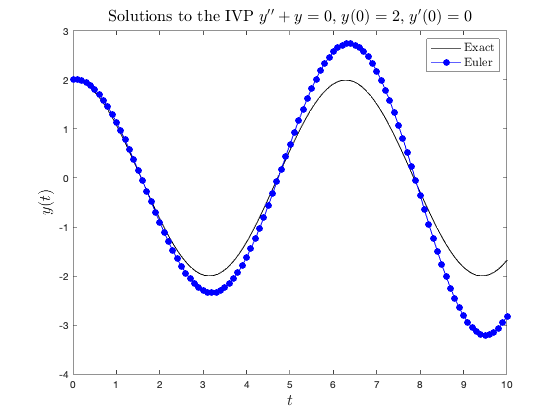

% Plot solution
t1 = linspace(tspan(2), tspan(1), 100);
plot(t1, exact(t1), 'k-')
hold on
plot(t, y(:, 1), 'bo-', 'MarkerFaceColor', 'b')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the IVP $y'' + y = 0$, $y(0)=2$, $y'(0)=0$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'Euler');
set(leg, 'Location', 'Northeast', 'FontSize', 12, 'Interpreter', 'latex')

Here we can see that the Euler method solution is deviating away from the exact solution. Once again this is a result of the lower order accuracy of the Euler method.

## Summary

- An initial value problem is expressed as an ODE where the solution at the lower bound of the domain is known.

- The Euler method is derived by truncating the Taylor series after the first-order term. It advances the solution over a small step of length $h$ using known values of $t_n$ and $y_n$ to calculate the solution at $y_{n+1}=y(t_n+h)$.

- The Euler method is only first-order accurate so the solutions tend to be inaccurate unless using a very small value of $h$.

- Higher-order ODEs can be rewritten as systems of first-order ODEs which can be solved using numerical solvers.

## Exercises

1. Using pen and a calculator (i.e., not MATLAB) solve the following IVP using the Euler method with a step length of $h=0.4$. Write down your solutions correct to 4 decimal places.


$$y\prime=ty, \qquad t\in[0,2], \qquad y(0)=1.$$


2. Reproduce your solutions to question 1 using a MATLAB program.

3. The exam solution to the IVP in question 1 is $y=e^{t^2/2}$. Produce a plot of the Euler solution from question 2 and the exact solution on the same set of axes.

## Functions

The functions used in this page are defined in this section.

#### The Euler method

function [t, y] = euler(f, tspan, y0, h)

% Calculuates the solution to an IVP using the Euler method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, 1);
t(1) = tspan(1);
y(1) = y0;

% Solver loop
for n = 1 : nsteps
    y(n + 1) = y(n) + h * f(t(n), y(n));
    t(n + 1) = t(n) + h;
end

end

#### The Euler method for solving a system of ODEs

function [t, y] = euler2(f, tspan, y0, h)

% Calculuates the solution to an IVP expressed using a system of first-order
% ODEs using the Euler method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, length(y0));
t(1) = tspan(1);
y(1, :) = y0';

% Solver loop
for n = 1 : nsteps
    y(n + 1, :) = y(n, :) + h * f(t(n), y(n, :));
    t(n + 1) = t(n) + h;
end

end